clear;
clc;

file_paths = {'location(5,3)responder1.txt', 'location(5,3)responder2.txt', 'location(5,3)responder3.txt', 'location(5,3)responder4new.txt', 'location(5,3)responder5.txt'};
test_file_paths = {'location(6,2)responder1.txt', 'location(6,2)responder2.txt', 'location(6,2)responder3.txt', 'location(6,2)responder4.txt', 'location(6,2)responder5.txt'};

all_CIR_real_all = {};
all_CIR_imag_all = {};

% Boucle pour lire les valeurs CIR de chaque fichier d'entraînement
for i = 1:length(file_paths)
    file_path = file_paths{i};
    [CIR_real_all, CIR_imag_all] = readCIRValuesFromMeasurments(file_path);
    all_CIR_real_all{i} = CIR_real_all;
    all_CIR_imag_all{i} = CIR_imag_all;
    disp(['Total number of read CIR pairs for ', file_path, ': ', num2str(length(CIR_real_all))]);
end

Total number of read CIR pairs for location(5,3)responder1.txt: 984
Total number of read CIR pairs for location(5,3)responder2.txt: 1034
Total number of read CIR pairs for location(5,3)responder3.txt: 1028
Total number of read CIR pairs for location(5,3)responder4new.txt: 1006
Total number of read CIR pairs for location(5,3)responder5.txt: 1032


disp(['==========================================================================']);         


% Initialiser les vecteurs pour les caractéristiques et les étiquettes d'entraînement
features = [];
labels = [];

% Boucle pour générer les caractéristiques pour chaque fichier d'entraînement
for i = 1:length(file_paths)
    file_path = file_paths{i};
    CIR_real_all = all_CIR_real_all{i};
    CIR_imag_all = all_CIR_imag_all{i};

    for CIRNumber = 1:length(CIR_real_all)
        % Extraire les valeurs réelles et imaginaires
        CIR_real = CIR_real_all{CIRNumber}(735:820)';
        CIR_imag = CIR_imag_all{CIRNumber}(735:820)';
        
        % Calculer les valeurs complexes et leurs métriques
        CIR_complex_values = CIR_real + 1i * CIR_imag;
        CIR_phase = angle(CIR_complex_values);

        % Calculer les caractéristiques
        varPhase_value = var(CIR_phase);
        stdPhase_value = std(CIR_phase);
        ratio_negative_phases = sum(CIR_phase < 0) / length(CIR_phase);

        % Ajouter les caractéristiques à l'ensemble de données
        features = [features; varPhase_value, stdPhase_value, ratio_negative_phases];

        % Ajouter les étiquettes (0 pour LOS, 1 pour NLOS)
        if strcmp(file_path, 'location(5,3)responder5.txt')
            labels = [labels; 1]; % NLOS
        else
            labels = [labels; 0]; % LOS
        end
    end
end

% Séparer les données en ensemble d'entraînement et de test
cv = cvpartition(labels, 'HoldOut', 0.3);
trainIdx = training(cv);
testIdx = test(cv);

% Forêts Aléatoires
randomForestModel = TreeBagger(100, features(trainIdx, :), labels(trainIdx), 'Method', 'classification');

% Prédiction sur l'ensemble de test interne
[predictions_internal_rf, scores_internal_rf] = predict(randomForestModel, features(testIdx, :));
predictions_internal_rf = str2double(predictions_internal_rf);

% Évaluation des performances sur l'ensemble de test interne
accuracy_internal_rf = sum(predictions_internal_rf == labels(testIdx)) / length(labels(testIdx));
disp(['Random Forest Internal Test Set Accuracy: ', num2str(accuracy_internal_rf)]);

Random Forest Internal Test Set Accuracy: 0.73115



% Matrice de confusion pour l'ensemble de test interne
confMat_internal_rf = confusionmat(labels(testIdx), predictions_internal_rf);
disp('Random Forest Internal Confusion Matrix:');

Random Forest Internal Confusion Matrix:


disp(confMat_internal_rf);

        1052         164
         246          63




% Validation croisée pour le modèle de Forêt Aléatoire
cv_rf = cvpartition(labels, 'KFold', 10);
accuracy_rf_cv = zeros(cv_rf.NumTestSets, 1);
for i = 1:cv_rf.NumTestSets
    trainIdx_rf = training(cv_rf, i);
    testIdx_rf = test(cv_rf, i);
    
    model_rf_cv = TreeBagger(100, features(trainIdx_rf, :), labels(trainIdx_rf), 'Method', 'classification');
    predictions_rf_cv = predict(model_rf_cv, features(testIdx_rf, :));
    predictions_rf_cv = str2double(predictions_rf_cv);
    
    accuracy_rf_cv(i) = sum(predictions_rf_cv == labels(testIdx_rf)) / length(labels(testIdx_rf));
end
disp(['Random Forest Cross-Validation Accuracy: ', num2str(mean(accuracy_rf_cv))]);

Random Forest Cross-Validation Accuracy: 0.7443



% Prédiction sur l'ensemble de test externe
test_features = [];
test_labels = [];

% Boucle pour générer les caractéristiques pour chaque fichier de test
for i = 1:length(test_file_paths)
    file_path = test_file_paths{i};
    [CIR_real_all, CIR_imag_all] = readCIRValuesFromMeasurments(file_path);

    for CIRNumber = 1:length(CIR_real_all)
        % Extraire les valeurs réelles et imaginaires
        CIR_real = CIR_real_all{CIRNumber}(735:820)';
        CIR_imag = CIR_imag_all{CIRNumber}(735:820)';
        
        % Calculer les valeurs complexes et leurs métriques
        CIR_complex_values = CIR_real + 1i * CIR_imag;
        CIR_phase = angle(CIR_complex_values);

        % Calculer les caractéristiques
        varPhase_value = var(CIR_phase);
        stdPhase_value = std(CIR_phase);
        ratio_negative_phases = sum(CIR_phase < 0) / length(CIR_phase);

        % Ajouter les caractéristiques à l'ensemble de données de test
        test_features = [test_features; varPhase_value, stdPhase_value, ratio_negative_phases];

        % Ajouter les étiquettes (0 pour LOS, 1 pour NLOS)
        if strcmp(file_path, 'location(6,2)responder5.txt')
            test_labels = [test_labels; 1]; % NLOS
        else
            test_labels = [test_labels; 0]; % LOS
        end
    end
end

[predictions_external_rf, scores_external_rf] = predict(randomForestModel, test_features);
predictions_external_rf = str2double(predictions_external_rf);

% Évaluation des performances sur l'ensemble de test externe
accuracy_external_rf = sum(predictions_external_rf == test_labels) / length(test_labels);
disp(['Random Forest External Test Set Accuracy: ', num2str(accuracy_external_rf)]);

Random Forest External Test Set Accuracy: 0.71492



% Matrice de confusion pour l'ensemble de test externe
confMat_external_rf = confusionmat(test_labels, predictions_external_rf);
disp('Random Forest External Confusion Matrix:');

Random Forest External Confusion Matrix:


disp(confMat_external_rf);

        3520         601
         868         164



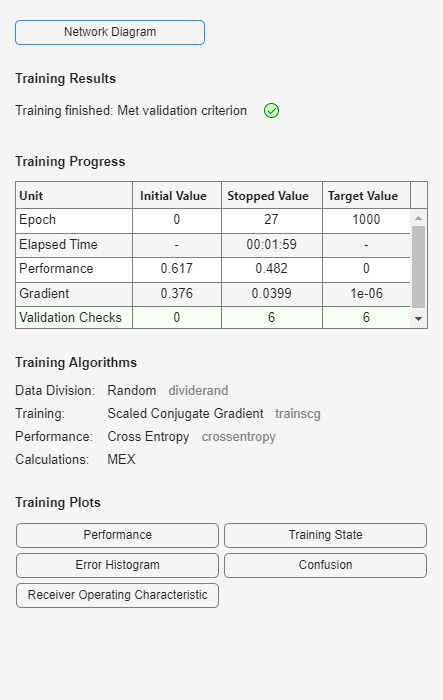


% Réseaux de Neurones
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize);

% Entraîner le réseau de neurones
[net, tr] = train(net, features(trainIdx, :)', labels(trainIdx)');


% Prédiction sur l'ensemble de test interne
predictions_internal_nn = net(features(testIdx, :)');
predictions_internal_nn = round(predictions_internal_nn); % Arrondir les prédictions aux classes 0 et 1

% Évaluation des performances sur l'ensemble de test interne
accuracy_internal_nn = sum(predictions_internal_nn == labels(testIdx)') / length(labels(testIdx));
disp(['Neural Network Internal Test Set Accuracy: ', num2str(accuracy_internal_nn)]);

Neural Network Internal Test Set Accuracy: 0.79738



% Matrice de confusion pour l'ensemble de test interne
confMat_internal_nn = confusionmat(labels(testIdx), predictions_internal_nn');
disp('Neural Network Internal Confusion Matrix:');

Neural Network Internal Confusion Matrix:


disp(confMat_internal_nn);

        1216           0
         309           0




% Prédiction sur l'ensemble de test externe
predictions_external_nn = net(test_features');
predictions_external_nn = round(predictions_external_nn); % Arrondir les prédictions aux classes 0 et 1

% Évaluation des performances sur l'ensemble de test externe
accuracy_external_nn = sum(predictions_external_nn == test_labels') / length(test_labels);
disp(['Neural Network External Test Set Accuracy: ', num2str(accuracy_external_nn)]);

Neural Network External Test Set Accuracy: 0.79973



% Matrice de confusion pour l'ensemble de test externe
confMat_external_nn = confusionmat(test_labels, predictions_external_nn');
disp('Neural Network External Confusion Matrix:');

Neural Network External Confusion Matrix:


disp(confMat_external_nn);

        4121           0
        1032           0

